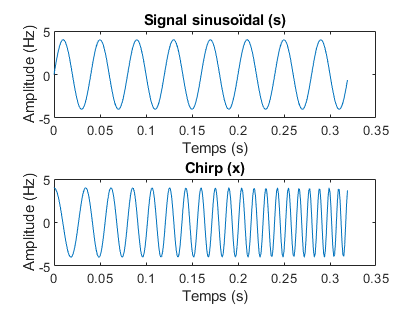

% Brullard Baptiste
close all;
clear all;

% Question 1
f0 = 25;
fe = 1000;
te = 1/fe;
N = 320;
A = 4;
TMax = (te*(N-1));
t = 0:te:TMax;
s = A*sin(2*pi*f0*t);

% Question 2
f1 = 100;
x = A*chirp(t,f0,t(end),f1);

% Question 3
figure;
subplot(211);
plot(t, s);
title('Signal sinusoïdal (s)');
xlabel('Temps (s)')
ylabel('Amplitude (Hz)');
subplot(212);
plot(t, x);
title('Chirp (x)');
xlabel('Temps (s)')
ylabel('Amplitude (Hz)');


% Question 4
Ps = sum(s.^2)/length(s)

Ps = 8.0000


% Question 5
Psth = A^2/2

Psth = 8

% La valeur obtenue correspond bien à la valeur théorique

% Question 6
Px = sum(x.^2)/length(x)

Px = 8.0115

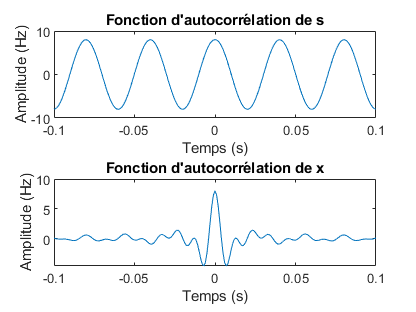


% Question 7
[rs, lags1] = xcorr(s, 100, 'unbiased');
tau1 = lags1*te;

[rx, lags2] = xcorr(x, 100, 'unbiased');
tau2 = lags2*te;

figure;
subplot(211);
plot(tau1, rs);
title('Fonction d''autocorrélation de s');
xlabel('Temps (s)');
ylabel('Amplitude (Hz)');
subplot(212);
plot(tau2, rx);
title('Fonction d''autocorrélation de x');
xlabel('Temps (s)');
ylabel('Amplitude (Hz)');

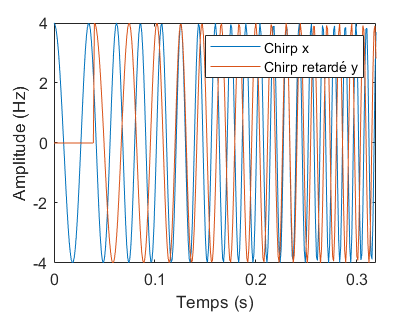


% Question 8 : en 0 on retrouve bien l'amplitude du signal

% Question 9
y = [zeros(1,40) x(1:(end-40))];

figure;
plot(t, x, t, y);
legend('Chirp x', 'Chirp retardé y');
xlabel('Temps (s)');
ylabel('Amplitude (Hz)');


% Question 10 : 0.05 sec

% Question 11 : signal bruité
b = rand(size(t));
b = b - mean(b);
b = b/std(b);
b = b*sqrt(8);
var = var(b) % pour vérifier

var = 8.0000

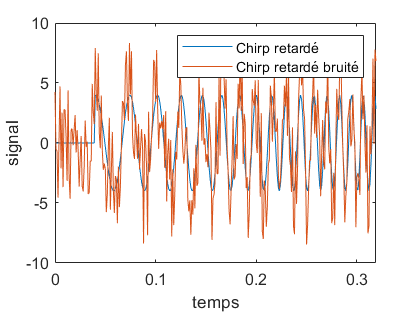


% Question 12 : puissance du bruit
Pb = sum(b.^2)/N;

% Question 13 : valeur du rapport signal sur bruit (en dB)
Py = sum(y.^2)/N;
rap = 10*log10(Py/Pb);

% Question 14 : représentation du signal bruité
yb = y + b;
figure;
plot(t,y,t,yb);
legend('Chirp retardé','Chirp retardé bruité');
xlabel('temps');
ylabel('signal');

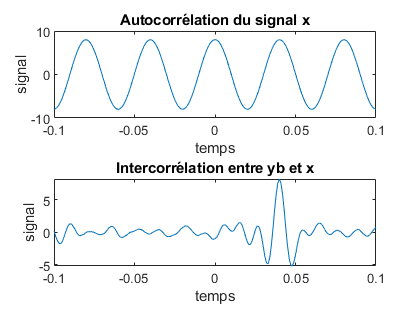


% Question 15 : intercorrélation entre yb et x
[rybx, lags3] = xcorr(yb,x,100,'unbiased');
tau3 = lags3*te;

% Question 16 : répresensation graphique (l'axe du temps est pas retardé
% par contre)
figure;
subplot(211);
plot(tau2,rs);
title('Autocorrélation du signal x');
xlabel('temps');
ylabel('signal');
subplot(212);
plot(tau3,rybx);
xlabel('temps');
ylabel('signal');
title('Intercorrélation entre yb et x');


% Question 18 : max de l'intercorrélation
[v,nmax]=max(rybx);
tauMax=tau3(nmax)

tauMax = 0.0400